# # 2024-08-20 - Computer Vision (CV) Posterior Analyses 

addpath(genpath('helpers'));

%img_path = fullfile("C:\Users\pho\repos\Spike3DWorkEnv\Spike3D\output\_temp_individual_posteriors\2024-08-21\laps\greyscale");
img_path = fullfile("/home/halechr/Desktop/_temp_individual_posteriors/2024-08-21/laps/greyscale");
img_path

img_path = "/home/halechr/Desktop/_temp_individual_posteriors/2024-08-21/laps/greyscale"

imdsTrain = imageDatastore(img_path,'IncludeSubfolders',true);
imdsTrain.readall("UseParallel",true)

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


ans = 84×1 cell array
    {1024×1185 uint8}
    {1024×5209 uint8}
    {1024×3844 uint8}
    {1024×4814 uint8}
    {1024×4634 uint8}
    {1024×5048 uint8}
    {1024×3341 uint8}
    {1024×5245 uint8}
    {1024×6413 uint8}
    {1024×4060 uint8}
    {1024×4473 uint8}
    {1024×1832 uint8}
    {1024×4401 uint8}
    {1024×3269 uint8}
    {1024×4113 uint8}
    {1024×3844 uint8}


imageBatchProcessor(imdsTrain)

processed_images

processed_images = 84×5 table
            bw                  imgray                seg_bw            seg_maskedImage                                                  fileName                                              
    ___________________    _________________    ___________________    _________________    ___________________________________________________________________________________________________

    {1024×4060 logical}    {1024×4060 uint8}    {1024×4060 logical}    {1024×4060 uint8}    {'/home/halechr/Desktop/_temp_individual_posteriors/2024-08-21/laps/greyscale/p_x_given_n[18].png'}
    {1024×4473 logical}    {1024×4473 uint8}    {1024×4473 logical}    {1024×4473 uint8}    {'/home/halechr/Desktop/_temp_individual_posteriors/2024-08-21/laps/greyscale/p_x_given_n[19].png'}
    {1024×1832 logical}    {102

Image Processing Interactive

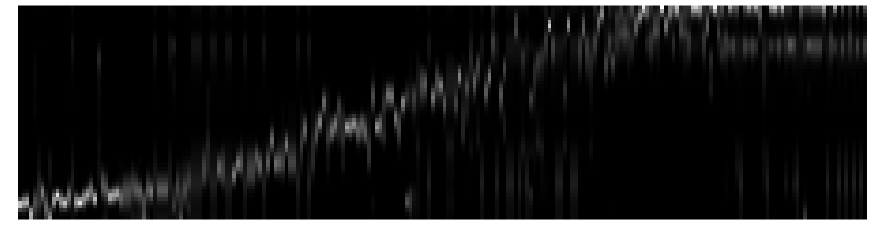

%im = processed_images.seg_bw{1};
im = processed_images.imgray{1};
bw = processed_images.seg_bw{1};

figure(1); imshow(im);

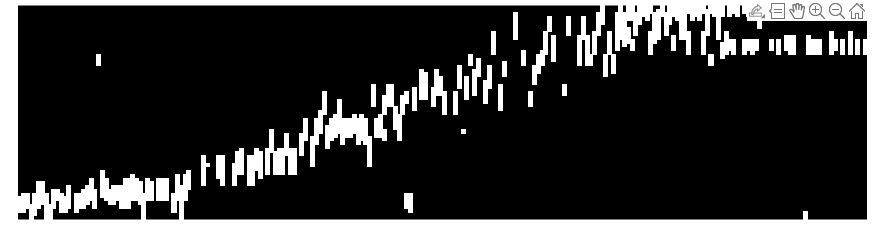

figure(2); imshow(bw);

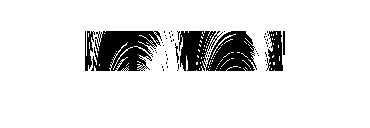

imP = ImToPolar(im, 0.6, 1, 40, 200);
figure(2); imshow(imP);

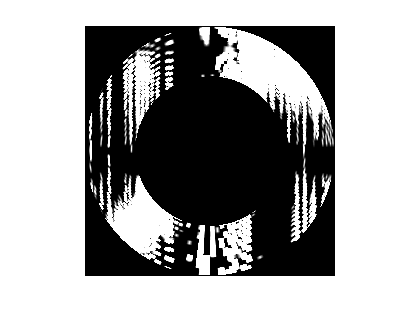

imR = PolarToIm(imP, 0.6, 1, 250, 250);
figure(3); imshow(imR);

rMin = 0.25; rMax = 0.8;

% Rotation invariant image moments
%moment(im)
inv_moments = Hu_Moments(im)

inv_moments = 1×7 uint8 row vector
   0   0   0   0   0   0   0


%eta = SI_Moment(im, bw)
%cen_mmt = Centr_Moment(im,bw)
%F = IMOMENTS(im)


% https://raphael.candelier.fr/?blog=Image%20Moments

E = IM.get_ellipse(bw)                % Compute the equivalent ellipse

E = struct with fields:
      m00: 447928
      m10: 910944049
      m01: 206499275
      m11: 2.6644e+11
      m02: 1.4244e+11
      m20: 2.4393e+12
        x: 2.0337e+03
        y: 461.0100
    theta: -0.2587
        w: 243.2100
        l: 2.3670e+03
       x1: 4.3098e+03
       y1: -141.2674
       x2: -242.4124
       y2: 1.0633e+03


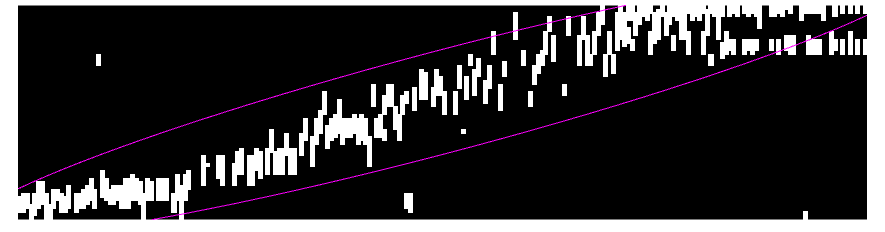

imshow(bw)
hold on
IM.draw_ellipse(E, 'color', 'm')

% Read the sample image in
im = imgray{1}; % imread('shapessm.jpg');

Undefined variable 'imgray'.

im

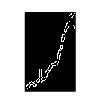


% Find edges using the Canny operator with hysteresis thresholds of 0.1
% and 0.2 with smoothing parameter sigma set to 1.
edgeim = edge(im,'canny', [0.1 0.2], 1);

figure(1), imshow(edgeim);

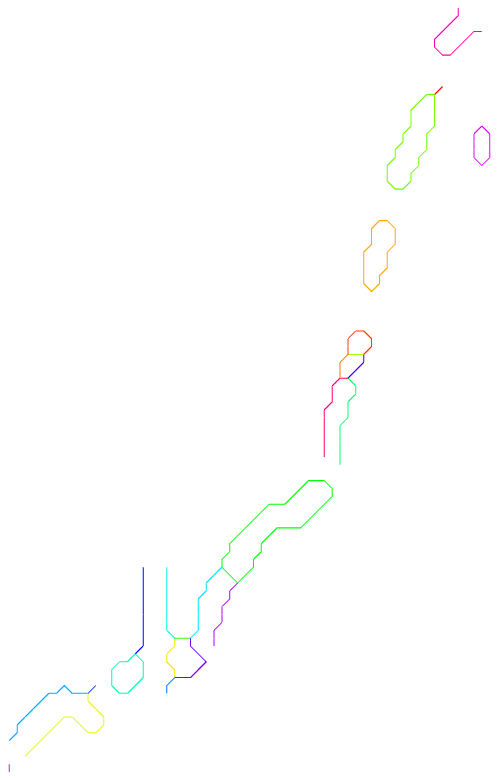

% Link edge pixels together into lists of sequential edge points, one
% list for each edge contour. A contour/edgelist starts/stops at an 
% ending or a junction with another contour/edgelist.
% Here we discard contours less than 10 pixels long.

[edgelist, labelededgeim] = edgelink(edgeim, 10);

% Display the edgelists with random colours for each distinct edge 
% in figure 2

drawedgelist(edgelist, size(im), 1, 'rand', 2); axis off  

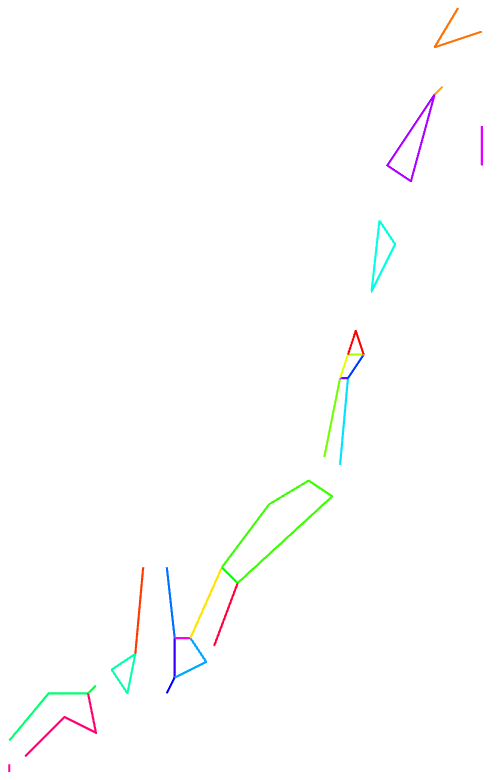

% Fit line segments to the edgelists
tol = 2;         % Line segments are fitted with maximum deviation from
	     % original edge of 2 pixels.
seglist = lineseg(edgelist, tol);

% Draw the fitted line segments stored in seglist in figure window 3 with
% a linewidth of 2 and random colours
drawedgelist(seglist, size(im), 2, 'rand', 3); axis off

S = fastradial(im, [1 3 5], 2, 0)

S =    -0.3410   -0.1828   -0.1221   -0.1095   -0.1167   -0.1296   -0.1395   -0.1436   -0.1446   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1448   -0.1450   -0.1474   -0.1584   -0.1850   -0.2222   -0.2665
   -0.1817    0.0936   -0.0364   -0.0174   -0.0300   -0.0445   -0.0531   -0.0574   -0.0587   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0590   -0.0592   -0.0610   -0.0698   -0.0916   -0.1228   -0

# Mean square displacement analysis of particle trajectories

% ma = msdanalyzer(2, 'µm', 's')

ma =   msdanalyzer with properties:

      TOLERANCE: 12
         tracks: {}
          n_dim: 2
    space_units: 'µm'
     time_units: 's'
            msd: []
          vcorr: []
           lfit: []
      loglogfit: []
          drift: []

# Tracking

% SPACE_UNITS = 'µm';
% TIME_UNITS = 's';
% 
% N_PARTICLES = 1;
% N_TIME_STEPS = 1861;
% %N_DIM = 2; % 2D
% N_DIM = 1; % 1D
% 
% % Typical values taken from studies of proteins diffusing in membranes:
% % Diffusion coefficient
% D  = 1e-3; % µm^2/s
% % Time step between acquisition; fast acquisition!
% dT = 0.05; % s,
% 
% % Area size, just used to disperse particles in 2D. Has no impact on
% % analysis.
% SIZE = 2; % µm
% k = sqrt(2 * D * dT);

% tracks = cell(N_PARTICLES, 1);
% 
% for i = 1 : N_PARTICLES
% 
%     % Time
%     time = (0 : N_TIME_STEPS-1)' * dT;
% 
%     % Initial position
%     X0 = SIZE .* rand(1, N_DIM);
% 
%     % Integrate uncorrelated displacement
%     dX = k * randn(N_TIME_STEPS, N_DIM);
%     dX(1, :) = X0;
%     X = cumsum(dX, 1);
% 
%     size(time)
%     size(X)
%     % Store
%     tracks{i} = [time X];
% 
% end

ans =         1861           1


ans =         1861           1


% clear i X dX time X0

% tracks = cell(N_PARTICLES, 1);
% tracks{1} = flat_tracks;

% ma = msdanalyzer(N_DIM, SPACE_UNITS, TIME_UNITS);
% % This does not work:
% %ma.addAll(tracks);
% 
% % This works:
% ma = ma.addAll(tracks);
% 
% % Indeed:
% disp(ma)

  msdanalyzer with properties:

      TOLERANCE: 12
         tracks: {[1861×2 double]}
          n_dim: 1
    space_units: 'µm'
     time_units: 's'
            msd: []
          vcorr: []
           lfit: []
      loglogfit: []
          drift: []


Error using msdanalyzer/plotTracks (line 29)
Can only plot tracks for 2D or 3D problems, got 1D.

Error using msdanalyzer/labelPlotTracks (line 12)
Can only label axis for 2D or 3D problems, got 1D.